clc; clear; close all;

## Task 1

input_vid = VideoReader('MiniProject1_28626\MiniProject1\task1.mp4');
output_vid = VideoWriter('task1_output.avi');
open(output_vid);

% estimated runtime: 6.6 seconds
for i=1:input_vid.NumberOfFrames
    
    % Convert each frame to grayscale
    frame = rgb2gray(read(input_vid, i));
    
    % Downsample each frame for faster runtime
    downsampled_frame = double(frame(1:3:end, 1:3:end));
    
    % Perform Sobel edge detection
    frame_edges = uint8(detect_edges(downsampled_frame));
    
    % Write each frame to the output video
    writeVideo(output_vid, frame_edges);

end

close(output_vid);
disp("Video created in the current working directory.")

Video created in the current working directory.


## Task 2

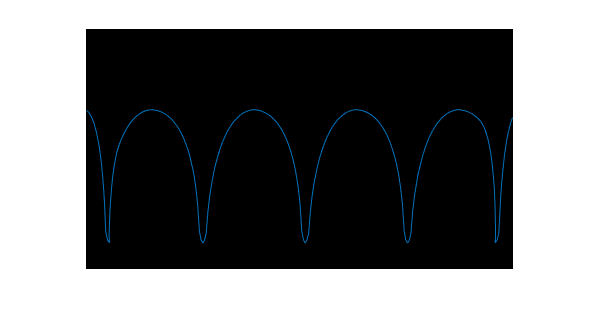

input_vid2 = VideoReader('MiniProject1_28626\MiniProject1\task2.mp4');

% Initialize a motion tracker
frame1 = double(rgb2gray(read(input_vid2, 1)));
frame1 = frame1(1:3:end, 1:3:end);
[x, y] = size(frame1);
tracker = zeros(x, y);

figure()
imshow(frame1)
hold on;

% estimated runtime: 9.18 seconds - looping over the non-zero frames
for i=4:291
    
    % Convert each frame to grayscale
    frame = double(rgb2gray(read(input_vid2, i)));
    
    % Downsample each frame for faster runtime
    downsampled_frame = frame(1:3:end, 1:3:end);
    
    % Segment foreground
    segmented_frame = double(imbinarize(downsampled_frame, 5));
    
    % Add motion difference
    tracker = tracker | segmented_frame;
    
    % Extract the centroid of the object in each frame
    centroids = regionprops(segmented_frame, 'Centroid');
    xCentroid = centroids.Centroid(1);
    yCentroid = centroids.Centroid(2);
    
    % Overlay centroid arrows on the first frame
    if(exist('old_xCentroid', 'var'))
        line([old_xCentroid xCentroid], [old_yCentroid yCentroid]);
    end
    
    old_xCentroid = xCentroid;
    old_yCentroid = yCentroid;
    
end

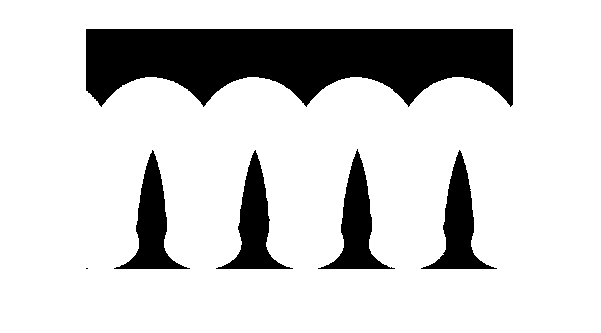

figure()
imshow(tracker)

# External Functions

function edges = detect_edges(img)
    % Edge detection using the Sobel operator
    % Compute the absolute gradient magnitude at each pixel

gx = [-1 0 1; -2 0 2; -1 0 1];
gy = [1 2 1; 0 0 0; -1 -2 -1];

edges = abs(convn(img, gx)) + abs(convn(img, gy));

end